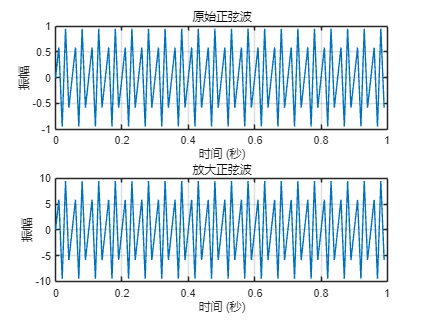

Fs = 100;              % 采样频率 (Hz)
duration = 1;           % 信号持续时间 (秒)
t = 0:1/Fs:duration-1/Fs; % 时间向量 
% 理解时间向量 0 起始值
% 步长 1/Fs 相当于每隔该步长则采集一次数据
%  duration则表示总时间，减去1/fs则说明是

% 生成一个440Hz的正弦波信号
f = 440;                % 正弦波频率 (Hz)
sine_wave = sin(2*pi*f*t);
% 放大正弦波
gain = 10; %放大因子
amplified_sine_wave = sine_wave * gain;
% 绘制信号
figure;
subplot(2, 1, 1);
plot(t, sine_wave);
title('原始正弦波');
xlabel('时间 (秒)');
ylabel('振幅');
grid on;

subplot(2,1,2);
plot(t,amplified_sine_wave);
title('放大正弦波');
xlabel('时间 (秒)');
ylabel('振幅');
grid on;